# Single driven-dissipative site

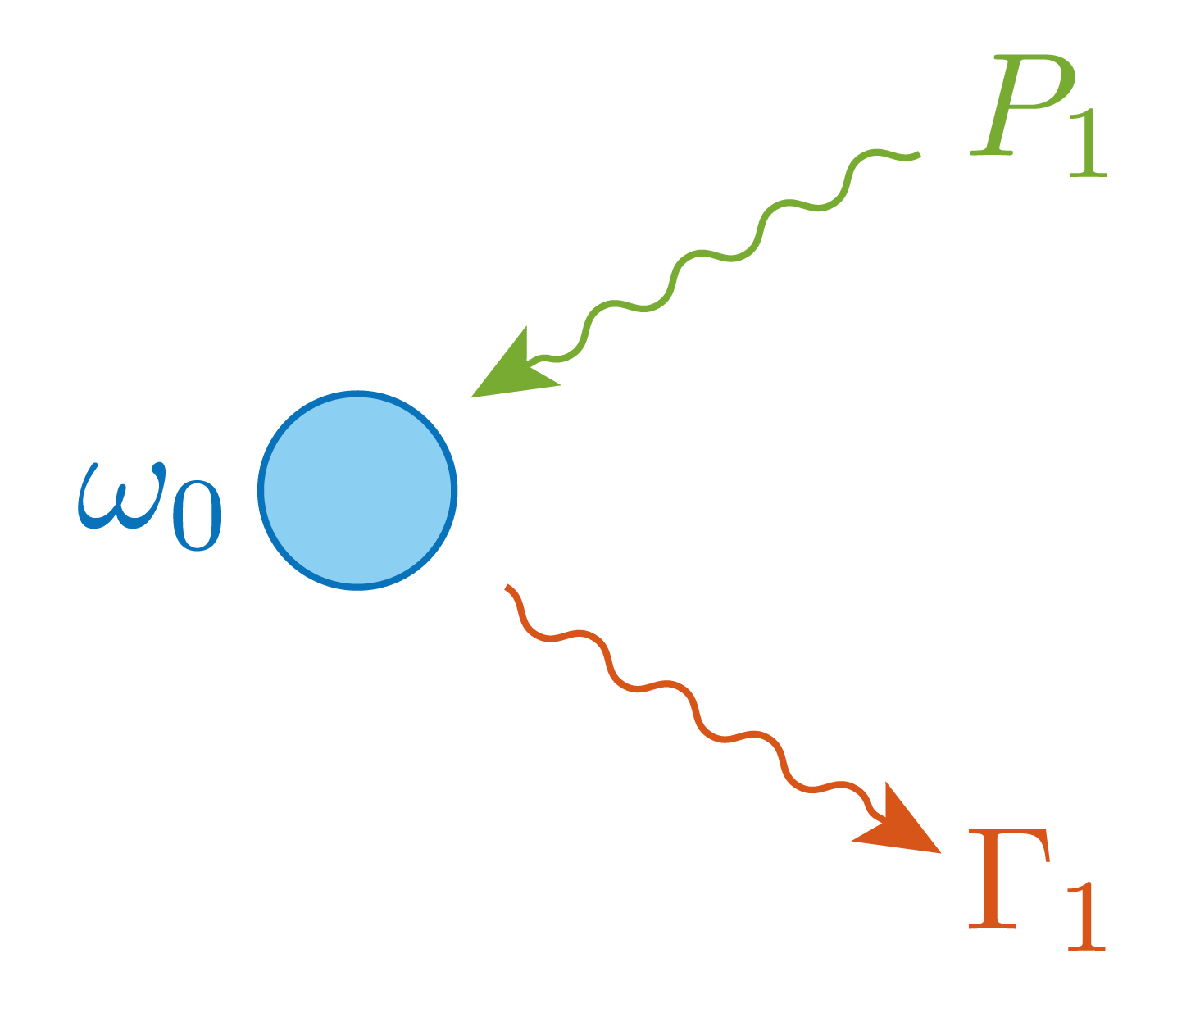

## Theory

Let's consider a single-mode, driven-dissipative bosonic/fermionic site.

### Hamiltonian

For the bosonic case, you can think about a harmonic oscillator or a photonic cavity, while for the fermionic case you can think about an energy level of a spinless fermion.

In both cases, the Hamiltonian is


$$H = \omega_0 a^{\dagger}a,$$


where $a$ and $a^{\dagger}$ destroy and create, respectively, a boson or a fermion. They obey the commutation relations


$$[a,a^{\dagger}]_{\pi} = aa^{\dagger} + \pi a^{\dagger}a = 1,$$


where $\pi =\pm$ and the upper (lower) sign applies for fermions (bosons).

Their action on Fock states is


$$a|n\rangle = \sqrt{n}|n-1\rangle \\
a^{\dagger}|n\rangle = \sqrt{n+1}|n+1\rangle$$


with the additional condition


$$a|0\rangle = a^{\dagger}|1\rangle = 0$$


for fermions (which essentially restricts the Fock states to $\left|0\rangle \right.$ and $\left|1\rangle \right.$ only).

In both cases, $N|n\rangle = a^{\dagger}a |n\rangle = n|n\rangle$.

### Dissipative dynamics

Let's also assume that the dissipative dynamics only involves single-particle processes, i.e. a process with jump operator $a$ describing single-particle losses at a rate $\Gamma_1$ and a process with jump operator $a^{\dagger}$ describing single-particle (incoherent) pumping at a rate $P_1$ (note: the subscript is just a reminder that these are single-particle rates).

In other words, the dissipator is


$$\mathcal{L}_D \rho = \Gamma_1 \Big( a \rho a^{\dagger} - \frac{1}{2} \big\{ a^{\dagger}a, \rho \big\} \Big) + P_1 \Big( a^{\dagger} \rho a - \frac{1}{2} \big\{ aa^{\dagger}, \rho \big\} \Big)$$


and the total dynamics is governed by the Lindblad equation


$$\partial_t\rho = \mathcal{L}\rho = -i \big[ H, \rho \big] + \mathcal{L}_D \rho.$$


### Vectorization

We vectorize the Lindblad equation by employing the formulation of quantum mechanics in Liouville space.

This involves purifying the identity operator $I$ into a *left vacuum* vector $|I\rangle$:


$$I = \sum_n | n \rangle \langle n |
\quad\Longrightarrow\qquad
| I \rangle = \sum_n | n \rangle \otimes | \tilde{n} \rangle$$


which satisfies $\langle I|\mathcal{L}=0$ and is then used to vectorize operators:


$$\mathcal{O}
\quad\Longrightarrow\quad
| \mathcal{O} \rangle = \mathcal{O} | I \rangle.$$


We can then vectorize the Lindblad equation by applying it to $|I\rangle$:


$$\partial_t\rho = \mathcal{L}\rho
\qquad\Longrightarrow\qquad
\partial_t | \rho \rangle = \mathcal{L} | \rho \rangle$$


where


$$\mathcal{L} | \rho \rangle =
-i \big( H - \tilde{H} \big) | \rho \rangle
+ \frac{\Gamma_1}{2} \big( 2\sigma a\tilde{a} - a^{\dagger}a - \tilde{a}^{\dagger}\tilde{a} \big) | \rho \rangle
+ \frac{P_1}{2} \big( 2\sigma a^{\dagger}\tilde{a}^{\dagger} - aa^{\dagger} - \tilde{a}\tilde{a}^{\dagger} \big) | \rho \rangle$$


and $\sigma =1$ for bosons and $\sigma =-i$ for fermions.

Rewritten as much as possible in terms of number operators:


$$\mathcal{L} =
-i \omega_0 \big( N - \tilde{N} \big)
- \frac{\Gamma_1+\pi P_1}{2} \big( N + \tilde{N} \big)
+ \sigma \big( \Gamma_1 a\tilde{a}
+ P_1 a^{\dagger}\tilde{a}^{\dagger} \big)
- P_1.$$


Here, the tilded operators act on the tilded Hilbert space only. For a general system operator $A$, the connection to its tilde-version is obtained by


$$A|I\rangle = \sigma_A {\tilde{A} }^{\dagger} |I\rangle,$$


where $\sigma_A =1$ for $A$ bosonic and $\sigma_A =-i$ for $A$ fermionic.

If $A$ is bosonic, an explicit form for $\tilde{A}$ is $\tilde{A} =I\otimes A^*$, directly mapping the above expression for the vectorized Lindblad equation to the Choi-Jamiołkowski isomorphism.

**Note:**

Since fermions anticommute, the fermionic Fock states for a single site in Liouville space are defined with the following phase factor:


$$|1,\tilde{0}\rangle = \sqrt{\sigma} a^{\dagger}|0,\tilde{0}\rangle,
\qquad
|0,\tilde{1}\rangle = \sqrt{\sigma} \tilde{a}^{\dagger}|0,\tilde{0}\rangle,
\qquad
|1,\tilde{1}\rangle = \sigma a^{\dagger}\tilde{a}^{\dagger} |0,\tilde{0}\rangle.$$


Since we are working with a single site we can employ the more convenient convention $\sigma =1$ (which is the one used in the code below). For multiple fermionic sites, it is still more convenient to employ the original $\sigma =-i$ instead.

## Numerics

Let's now simulate this model numerically.

initTasks;  % Octave compatibility

### Settings

We start by setting the parameters for the model.

Let's first choose whether we are simulating a fermionic or bosonic model:

isBosonic = true;

and define the phase factor $\sigma$ and the commutator sign $\pi$:

if isBosonic
    s = +1;  % sigma
    p = +1;  % pi
else
    s = +1;  % with -1i, code edits are necessary!
    p = -1;
end

You can prove (try to use the equation of motion technique!) that, for the model we have, you can always write the pump/loss rates as


$$\Gamma_1 = \Gamma^{\mathrm{eff}}\big(1 + \pi N_{\infty}\big),
\qquad
P_1 = \Gamma^{\mathrm{eff}} N_{\infty},$$


where


$$N_{\infty} = \frac{P_1}{\Gamma_1 - \pi P_1}$$


is the average steady-state occupation and


$$\Gamma^{\mathrm{eff}} = \Gamma_1 - \pi P_1$$


is the effective (or semiclassical) dissipation rate.

In this example, we simulate a system with an average steady-state occupation equal to 0.3 for the fermionic case, and 5 for the bosonic case:

Nss = 0.3*(1-isBosonic) + 5*isBosonic;
w0  = 1.0;              % omega_0
G1  = 0.1*(1 + p*Nss);  % Gamma_1
P1  = 0.1*(      Nss);  % P_1

In addition, while for fermions there are only 2 possible states ($|0\rangle$ and $|1\rangle$), for bosons we have to set a cutoff (maximum number of states) on the Hilbert space, for example 10 times the steady-state occupation:

Nc = 2*(1-isBosonic) + 10*Nss*isBosonic;

### Construction of vectorized Lindbladian

We now build the vectorized Lindbladian by first defining the regular and tilde fields:

startTime = stopWatch();
id0   = speye(Nc,Nc);                       % I
a0    = spdiags(sqrt(0:(Nc-1)).',1,Nc,Nc);  % a
a     = kron(a0,id0);                       % a  ⊗  I
at    = kron(id0,a0);                       % I  ⊗  a   (tilde-a)
id    = kron(id0,id0);                      % I  ⊗  I
aDag  = a';                                 % a† ⊗  I
atDag = at';                                % I  ⊗  a†  (tilde-a†)
N     = aDag*a;                             % N  ⊗  I
Nt    = atDag*at;                           % I  ⊗  N   (tilde-N)
stopWatch(startTime,'  [info] Fields construction in ');

At this point, we just put everything together:

startTime = stopWatch();
% Explicit form:
L = - 1i.*w0.*( N - Nt ) ...
    + G1.*( s.*a   *at    - aDag*a./2 - atDag*at./2 ) ...
    + P1.*( s.*aDag*atDag - a*aDag./2 - at*atDag./2 );
% % Number-oriented form:
% L = - 1i.*w0.*(N-Nt) ...
%     - 0.5.*(G1+p*P1).*(N+Nt) ...
%     + s.*(G1.*a*at+P1.*aDag*atDag) ...
%     - P1.*id;
stopWatch(startTime,'  [info] Lindbladian construction in ');

#### Exercise #1

- The two ways of writing the Lindbladian above should give exactly the same result in the fermionic case. Check that this is indeed the case.

- In the bosonic case, instead, this may not be the case. Why? How does the difference impact the result? (Hint: take a look at the numerical commutator)

### Steady-state density matrix

The steady-state density matrix $\rho_{\textrm{ss}}$ satisfies


$$0 = \partial_t \rho_{\mathrm{ss}} = \mathcal{L}\rho_{\mathrm{ss}}
\qquad\Longrightarrow\qquad
\mathcal{L} | \rho_{\mathrm{ss}} \rangle = 0,$$


i.e. it's the null-eigenvalue right eigenvector of the vectorized Lindbladian; the corresponding left eigenvector is the left vacuum $|I\rangle$.

Let's find these two vectors via sparse diagonalization:

startTime = stopWatch();
% Diagonalize
[pss,~] = eigs(L ,1,0);
[I  ,~] = eigs(L',1,0);
I = I';
% Normalize
prd = I*pss;
I   =   I./sqrt(prd);
pss = pss.*sqrt(prd)./prd;
stopWatch(startTime,'  [info] Steady-state obtained in ');

where we've also bi-normalized such that


$$\mathrm{Tr}\big(\rho_{\mathrm{ss}}\big) = 1
\qquad\Longrightarrow\qquad
\langle I | \rho_{\mathrm{ss}} \rangle = 1$$


% Check for normalization
disp(['  [info] <I|pₛₛ> = ',num2str(I*pss)]);

#### Exercise #2

- Check that, in the fermionic case, the numerical left vacuum is equal to the theoretical value, i.e. to [1, 0, 0, 1] up to an arbitrary constant, and that the smallest eigenvalue is exactly 0.

- Write down an explicit form of the 4×4 Lindbladian itself and verify that this holds analytically.

- In the bosonic case, instead, the may not the case. Why?

### Steady-state expectation values

Steady-state expectation values can now be calculated via


$$\langle \mathcal{O} \rangle = \mathrm{Tr}\big( \mathcal{O} \rho_{\mathrm{ss}}\big)
\qquad\Longrightarrow\qquad
\langle I | \mathcal{O} | \rho_{\mathrm{ss}} \rangle$$


For example, let's calculate $\langle N\rangle$ and check that it's equal to our theoretical expectation:

% Steady-state occupation
disp(['  [info] <I|N|pₛₛ> = ',num2str(I*N*pss)]);

#### Exercise #3

- Calculate the expectation value of the tilded number operator. Do you obtain the same value?

- Why do you think this is the case, and can you think of a situation in which the opposite happens?

### Full Lindbladian spectrum

You can perform a dense diagonalization to visualize the full spectrum of the Lindbladian.

**Careful!** In the bosonic case, this is only feasible for low cutoffs.

startTime = stopWatch();
eigVals = eig(full(L));
stopWatch(startTime,'  [info] Full spectrum obtained in ');
magicLaTeX;
figure;
plot(eigVals,'Marker','*','LineStyle','none');
curXLim = get(gca,'XLim');
set(gca,'XLim',[curXLim(1),max(curXLim(2),0)]);
xlabel('$\mathrm{Re}\mathcal{L}$');
ylabel('$\mathrm{Im}\mathcal{L}$');

What happens to the spectrum if you lower/raise the cutoff in the bosonic case?

### Time evolution

We can also use the vectorized form of the Lindblad equation to perform time evolution.

**Note:** vectorization, however, is not a prerequisite to do time evolution.

As a first step, we can evolve the density matrix in time:


$$\partial_t | \rho(t) \rangle = \mathcal{L} | \rho(t) \rangle$$


stateIdx     = (1+floor(Nc/5-1)*isBosonic)*Nc+(2+floor(Nc/5-1)*isBosonic);
Geff         = (G1-p*P1);         % effective loss rate
tSpan        = [0 5./Geff];       % up to 5 characteristic times
p0           = zeros(Nc^2,1);
p0(stateIdx) = 1;                 % density matrix in |1,1> or |10,10> pure state (with Nc = 50)
p0           = p0./(I*p0);        % bi-normalize against left vacuum
[tVec,pT]    = ode45(@(t,v) L*v, tSpan, p0);
pT           = pT.';              % time steps as cols of pT

Let's check that the evolution has preserved the trace of the density matrix:

magicLaTeX;
figure;
plot(tVec.*Geff,real(I*pT));
xlabel('$t\Gamma^{\mathrm{eff}}$');
ylabel('$\mathrm{Tr}\big(\rho(t)\big)$');

Then, we can calculate the time evolution of expectation values as:


$$\langle \mathcal{O}(t) \rangle = \langle I | \mathcal{O} | \rho(t) \rangle.$$


As an example, we can calculate the time evolution of $\langle N\left(t\right)\rangle$:

magicLaTeX;
figure;
plot(tVec.*Geff,real(I*N*pT),'DisplayName','Numerics'); hold on;
plot(tVec.*Geff,(real(I*N*p0)-Nss).*exp(-(G1-p*P1).*tVec)+Nss,'LineStyle','--','DisplayName','Theory');
legend;
xlabel('$t\Gamma^{\mathrm{eff}}$');
ylabel('$\langle N(t) \rangle$');

#### Exercise #4

- Derive the analytical formula for the time evolution of the average number of particles.

## DIY

In order to get yourself acquanted with the formalism, try to re-do this exercise for a Kerr (nonlinear) cavity, which has the following Hamiltonian:


$$H = \omega_0 a^{\dagger}a + U a^{\dagger}a^{\dagger}aa.$$


Are you still able to obtain any theoretical result in this case?

What if you also add two-particle losses? How would you write the dissipator in this case and how does it change the results?